# Plots

Medianen er det midterste data punkt i et ordnede data sæt.

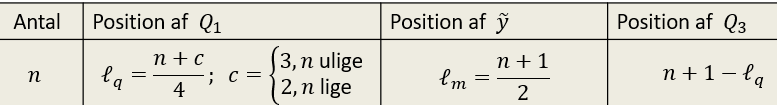

Hvis 2 tal er fundet som median tage gennemsnittet af disse

## Box plots

et **step ** er $1,5 \cdot (Q_3 - Q_1)$

Lower inner fence(LIF)


$$LIF = Q_1 - step$$


Upper inner fence(UIF)


$$UIF = Q_3 + step$$


Bogens metode -- andre steder kan man også bruge min og maximum værdien.

       mindste observation ≥LIF og 

       største observation ≤UIF

Det der er uden for dette er outliers

X = [2 3 5 7 9 10 15 16 16 19];
md = median(X) % finder medianen

md = 9.5000

q1 = prctile(X, 25) % finder første kvatil ved at finde data punkt ved 25%

q1 = 5

q3 = prctile(X, 75) % finder første kvatil ved at finde data punkt ved 75%

q3 = 16

Q = prctile(X, [25, 50, 75]) % finder alle 3 kvatiler ud fra 25% 50% 75% Q2 = medianen

Q =     5.0000    9.5000   16.0000


Q = quantile(X, 3) % finder alle 3 kvatiler ud fra procent

Q =     5.0000    9.5000   16.0000


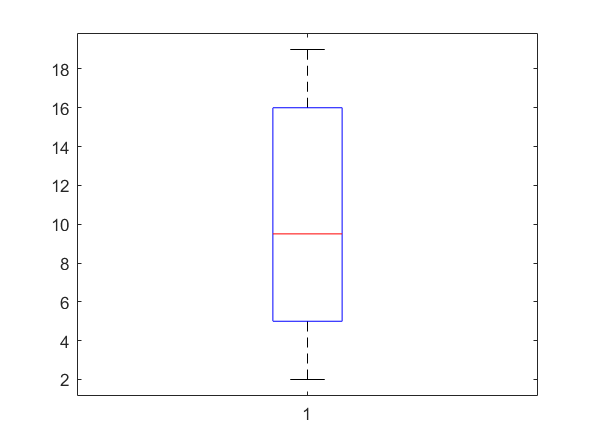


boxplot(X) % laver boxplot

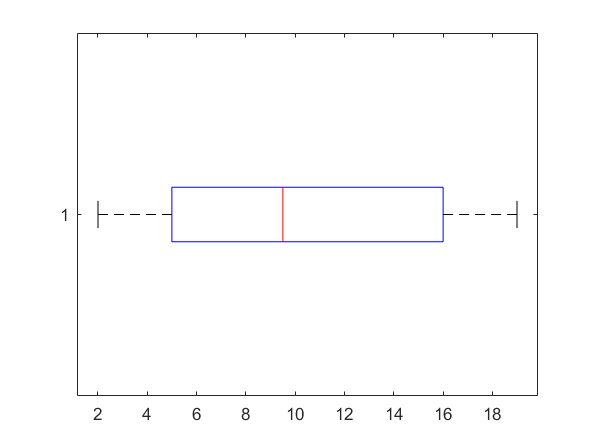

% boxplot(X, G) 
boxplot(X,'Orientation',"horizontal")

Eksempel

clear
data = xlsread("Eksamens sæt\18E\Data_M4STI1_2018E.xlsx");
bat1 = data(1:5,4)

bat1 =        11453
        8850
       10451
        8317
       10915


bat2 = data(6:10,4)

bat2 =         9027
        9794
        7493
        9204
        8319


bat3 = data(11:15,4)

bat3 =        10030
        8968
       10679
       11446
       10433


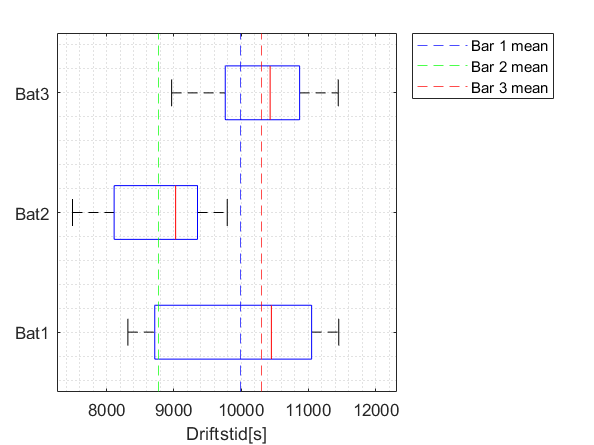


boxplot(data(1:15,4),data(1:15,3), 'Orientation','horizontal', ...
     "Labels", {'Bat1', 'Bat2', 'Bat3'})
xline(mean(bat1), '--b', 'DisplayName', 'Bar 1 mean')
xline(mean(bat2), '--g', 'DisplayName', 'Bar 2 mean')
xline(mean(bat3), '--r', 'DisplayName', 'Bar 3 mean')
xlabel('Driftstid[s]')
legend('location', 'northeastoutside')
grid("minor")

## Areal under kurve

clear
mu = 0.45

mu = 0.4500

Y = linspace(0,2.5,100);
y = 1

y = 1

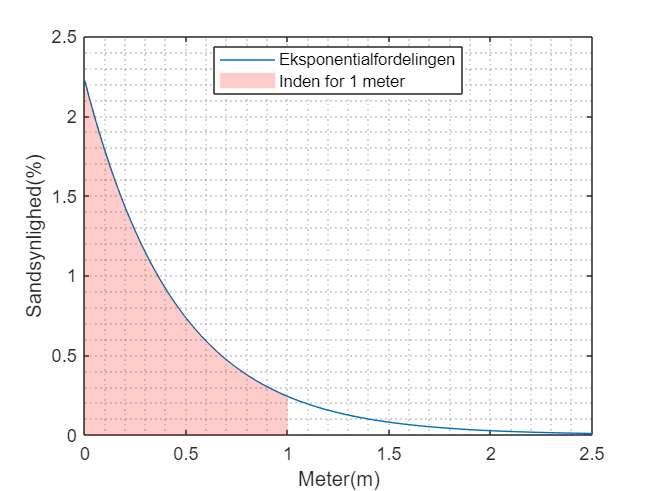


P = exppdf(Y, mu);
plot(Y, P,'DisplayName', 'Eksponentialfordelingen')
hold on
% xline(y, 'r--', DisplayName="Inden for " + y + " meter")
ylabel('Sandsynlighed(%)')
xlabel('Meter(m)')
legend('location', 'best')%, 'northeastoutside')
grid("minor")


%%%%%%%%  kode til areal under kuve  %%%%%
x = [0:0.1:y];
a1 = area(x,exppdf(x, mu),  ...
    DisplayName="Inden for " + y + " meter",  ...
    facecolor='r', ...
    EdgeColor='none'); % 'HandleVisibility','off',
alpha(a1, 0.2);

hold off